# Convolution Temps discret

close all;
clearvars;

## 
$$x\left [n \right]*h\left [n \right]=\sum_{k=-\infty}^{+\infty}x\left [k \right] h\left [ n- k\right ]
$$


## Convolution d'un echelon et d'une exponentielle

figure
N=100;
a=4/5; %prendre 0<a<1
n = -N/2:1:N/2-1

n =    -50   -49   -48   -47   -46   -45   -44   -43   -42   -41   -40   -39   -38   -37   -36   -35   -34   -33   -32   -31   -30   -29   -28   -27   -26   -25   -24   -23   -22   -21   -20   -19   -18   -17   -16   -15   -14   -13   -12   -11   -10    -9    -8    -7    -6    -5    -4    -3    -2    -1


u= [zeros(1,N/2) ones(1,N/2)]  % signal échelon

u =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x=u;
h= a.^n.*u;

tiledlayout(4,1)
nexttile()
stem(n,x)
title('x[n]');
nexttile()
stem(n,h)
title('y[n]');

Appel à la fonction conv

y1=conv(x,h,'same')

y1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


nexttile()
stem(n,y1)


y2=conv(h,x,'same')

y2 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


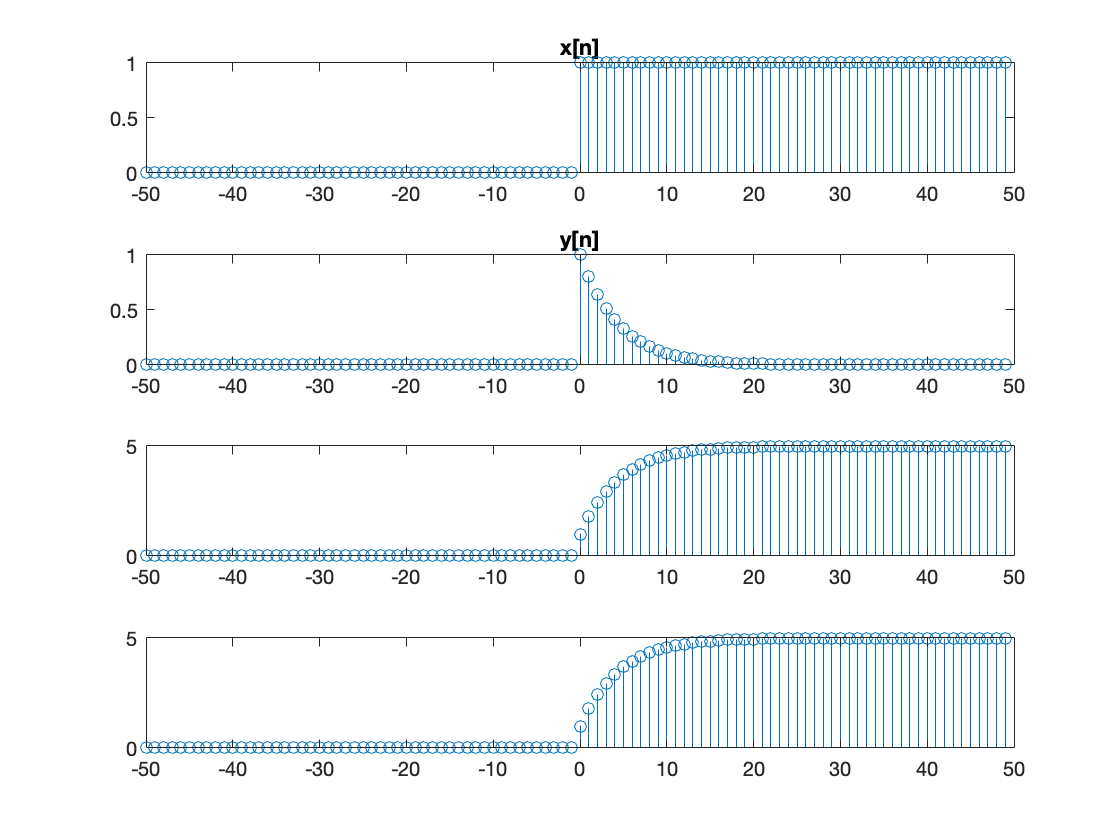

nexttile()
stem(n,y2)

Quelle propriété de la convolution est vérifiée?

# Approfondissement

## Convolution d'un echelon et d'une exponentielle à l'aide de l'intercorrélation

Intérêt : gestion automatique du décalage

figure
N=100;
a=4/5; %prendre 0<a<1
n = 0:N-1

n =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


u= ones(1,N) % signal échelon

u =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


x=u;
h= a.^n.*u;

tiledlayout(4,1)
nexttile()
stem(n,x)
title('x[n]');
nexttile()
stem(n,h)
title('h[n]');

nexttile()
[n,hinv]=inverseSignal(h)

n =   -100   -99   -98   -97   -96   -95   -94   -93   -92   -91   -90   -89   -88   -87   -86   -85   -84   -83   -82   -81   -80   -79   -78   -77   -76   -75   -74   -73   -72   -71   -70   -69   -68   -67   -66   -65   -64   -63   -62   -61   -60   -59   -58   -57   -56   -55   -54   -53   -52   -51


xinv =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


n =   -100   -99   -98   -97   -96   -95   -94   -93   -92   -91   -90   -89   -88   -87   -86   -85   -84   -83   -82   -81   -80   -79   -78   -77   -76   -75   -74   -73   -72   -71   -70   -69   -68   -67   -66   -65   -64   -63   -62   -61   -60   -59   -58   -57   -56   -55   -54   -53   -52   -51


hinv =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


[y,lag]=xcorr(x,hinv)

y =     0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000         0   -0.0000    0.0000         0   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000         0         0    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000


lag =   -199  -198  -197  -196  -195  -194  -193  -192  -191  -190  -189  -188  -187  -186  -185  -184  -183  -182  -181  -180  -179  -178  -177  -176  -175  -174  -173  -172  -171  -170  -169  -168  -167  -166  -165  -164  -163  -162  -161  -160  -159  -158  -157  -156  -155  -154  -153  -152  -151  -150


stem(lag(1:200)+99,y(1:200))
xlim([lag(1)+99,lag(200)+99])
title('Rxhinv');

nexttile()
[n,xinv]=inverseSignal(x)

n =   -100   -99   -98   -97   -96   -95   -94   -93   -92   -91   -90   -89   -88   -87   -86   -85   -84   -83   -82   -81   -80   -79   -78   -77   -76   -75   -74   -73   -72   -71   -70   -69   -68   -67   -66   -65   -64   -63   -62   -61   -60   -59   -58   -57   -56   -55   -54   -53   -52   -51


xinv =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


n =   -100   -99   -98   -97   -96   -95   -94   -93   -92   -91   -90   -89   -88   -87   -86   -85   -84   -83   -82   -81   -80   -79   -78   -77   -76   -75   -74   -73   -72   -71   -70   -69   -68   -67   -66   -65   -64   -63   -62   -61   -60   -59   -58   -57   -56   -55   -54   -53   -52   -51


xinv =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


[y,lag]=xcorr(h,xinv)

y =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000


lag =   -199  -198  -197  -196  -195  -194  -193  -192  -191  -190  -189  -188  -187  -186  -185  -184  -183  -182  -181  -180  -179  -178  -177  -176  -175  -174  -173  -172  -171  -170  -169  -168  -167  -166  -165  -164  -163  -162  -161  -160  -159  -158  -157  -156  -155  -154  -153  -152  -151  -150


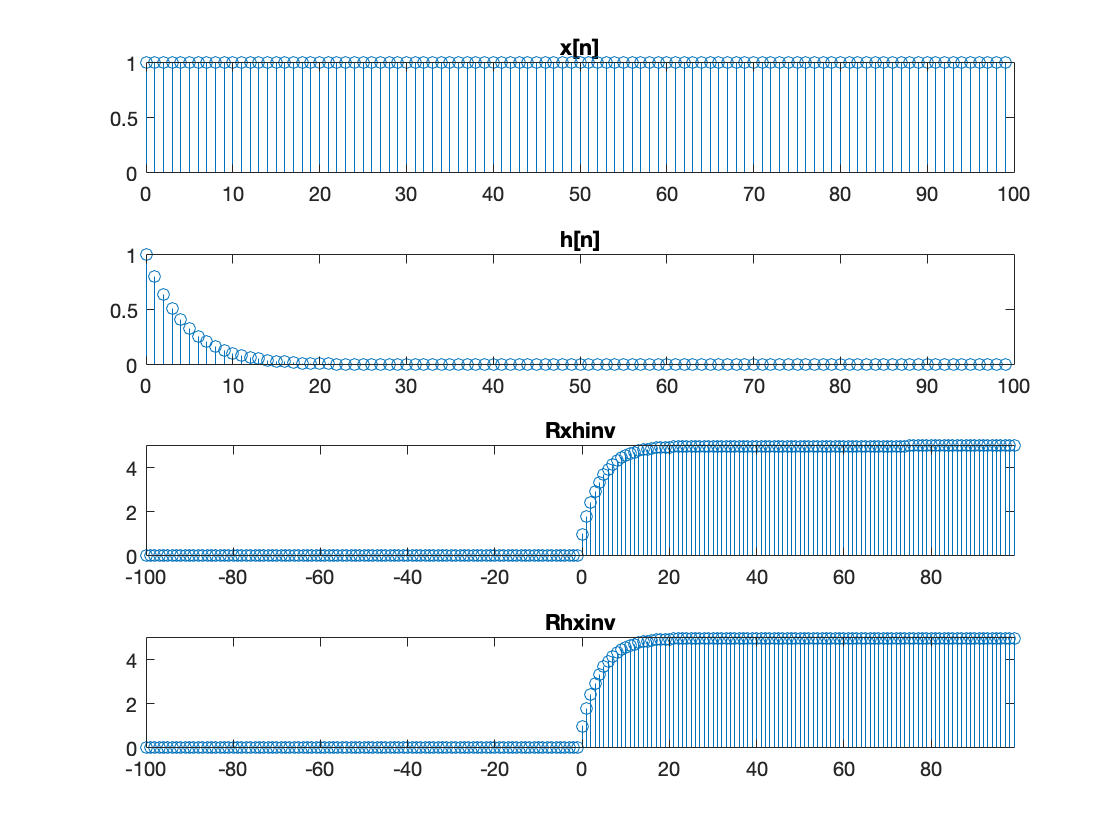

stem(lag(1:200)+99,y(1:200))
xlim([lag(1)+99,lag(200)+99])
title('Rhxinv');

## Déclaration de Fonctions

function [n,xinv]=inverseSignal(x)
n=-length(x):length(x)
xinv=[flip(x) zeros(1,length(x))]
return
end